## Ejercicio 2

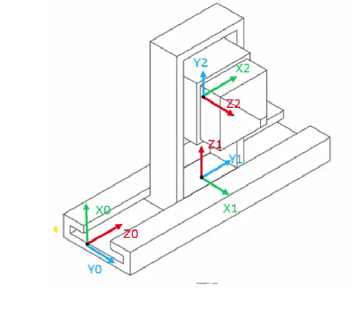

Para el robot prismático, las articulaciones se mueven sobre el eje z. Por lo que necesitamos encontrar 2 matrices de transformación homogenea para llegar al sistema de coordenadas final.

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms  t l1(t) l2(t) l3(t)

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[1 1 1];

%Creamos el vector de coordenadas articulares
Q= [l1, l2, l3];
%disp('Coordenadas generalizadas');
%pretty (Q);

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
%disp('Velocidades generalizadas');
%pretty (Qp);
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);


%Articulación 1
%Articulación 1 a Articulación 2
%Posición de la articulación 1 a 2

La articulación numero uno solo se mueve en su eje z y a la vez necesitaremos rotar su sistema de coordenadas en y 90° positivos y luego en z 90°.

P(:,:,1)= [0;0;l1];
%Matriz de rotación de la junta 1 a 2
R(:,:,1)=rotacion_y(90)*rotacion_z(90) ;

%Articulación 2
%Articulación 2 a Articulación 3
%Posición de la articulación 2 a 3

Para pasar del eje 2 al 3 es muy similar al anterior solo que aqui primero necesitaremos rotar en 90°positivos y luego en y otros 90°

P(:,:,2)= [0; 0;l2];
%Matriz de rotación de la junta 2 a 3
R(:,:,2)=  rotacion_x(90)*rotacion_y(90);

%Articulación 3 
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [0; 0;l3];

%Matriz de rotación de la junta 3 respecto a 2  0º
R(:,:,3)= [1 0 0;
           0 1 0;
           0 0 1;]

R = R(:,:,1) =

     0     0     1
     1     0     0
     0     1     0


R(:,:,2) =

     0     0     1
     1     0     0
     0     1     0


R(:,:,3) =

     1     0     0
     0     1     0
     0     0     1


%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str))
    T(:,:,i)= simplify(T(:,:,i))
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación global T1


$$\left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 1 & 0 & 0 & 0\\ 0 & 1 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{3}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

/ 0, 0, 1,   0   \
|                |
| 1, 0, 0,   0   |
|                |
| 0, 1, 0, l1(t) |
|                |
\ 0, 0, 0,   1   /



Matriz de Transformación global T2


$$\left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 1 & 0 & 0 & 0\\ 0 & 1 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 1 & 0 & l_{2}\left(t\right)\\ 0 & 0 & 1 & 0\\ 1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{3}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

/ 0, 1, 0, l2(t) \
|                |
| 0, 0, 1,   0   |
|                |
| 1, 0, 0, l1(t) |
|                |
\ 0, 0, 0,   1   /



Matriz de Transformación global T3


$$\left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 1 & 0 & 0 & 0\\ 0 & 1 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 1 & 0 & l_{2}\left(t\right)\\ 0 & 0 & 1 & 0\\ 1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 1 & 0 & l_{2}\left(t\right)\\ 0 & 0 & 1 & l_{3}\left(t\right)\\ 1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

/ 0, 1, 0, l2(t) \
|                |
| 0, 0, 1, l3(t) |
|                |
| 1, 0, 0, l1(t) |
|                |
\ 0, 0, 0,   1   /





%Calculamos el jacobiano lineal de forma diferencial
%disp('Jacobiano lineal obtenido de forma diferencial');
%Derivadas parciales de x respecto a th1 y th2
Jv11= functionalDerivative(PO(1,1,GDL), l1);
Jv12= functionalDerivative(PO(1,1,GDL), l2);
Jv13= functionalDerivative(PO(1,1,GDL), l3);
%Derivadas parciales de y respecto a th1 y th2
Jv21= functionalDerivative(PO(2,1,GDL), l1);
Jv22= functionalDerivative(PO(2,1,GDL), l2);
Jv23= functionalDerivative(PO(2,1,GDL), l3);
%Derivadas parciales de z respecto a th1 y th2
Jv31= functionalDerivative(PO(3,1,GDL), l1);
Jv32= functionalDerivative(PO(3,1,GDL), l2);
Jv33= functionalDerivative(PO(3,1,GDL), l3);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13;
              Jv21 Jv22 Jv23;
              Jv31 Jv32 Jv33]);
%pretty(jv_d);


%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 %Casos: articulación rotacional
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     %Para las juntas prismáticas
     elseif RP(k)==1 %Casos: articulación prismática
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);


Al final vemos que si existen velocidades lineales dependiendes de la distencia que recorren las articulaciones pero no hay vector de velocidades angulares ya que las articulaciones no rotan, solo se desplazan en sus ejes

disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/ ________ \
|  d       |
| -- l2(t) |
| dt       |
|          |
| ________ |
|  d       |
| -- l3(t) |
| dt       |
|          |
| ________ |
|  d       |
| -- l1(t) |
\ dt       /



disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
    pretty(W);

/ 0 \
|   |
| 0 |
|   |
\ 0 /



disp(W);

$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$



%funciones auxiliares para rotaciones
function Rx = rotacion_x(theta)
   
    Rx = [1,         0,           0;
          0, cosd(theta), -sind(theta);
          0, sind(theta),  cosd(theta)];
end


function Ry = rotacion_y(theta)
    % ROTACION_Y - Matriz de rotación alrededor del eje Y
    Ry = [ cosd(theta), 0, sind(theta);
                  0, 1,          0;
          -sind(theta), 0, cosd(theta)];
end

function Rz = rotacion_z(theta)
    % ROTACION_Z - Matriz de rotación alrededor del eje Z
    Rz = [cosd(theta), -sind(theta), 0;
          sind(theta),  cosd(theta), 0;
                 0,            0, 1];
end
